[A, B, C, D, G] = nominal();
[gm, pm, wcg, wcp] = margin(G)

gm = Inf

pm = 90

wcg = Inf

wcp = 1.0000

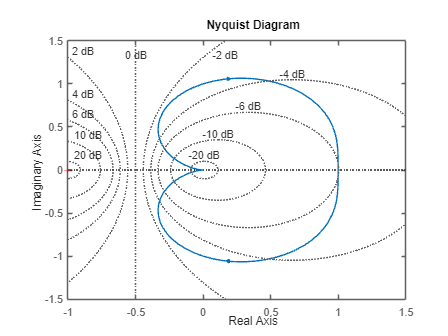

figure;
nyquist(G);
%title('Nyquist Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/nyquist_G.png', '-dpng', '-r300');

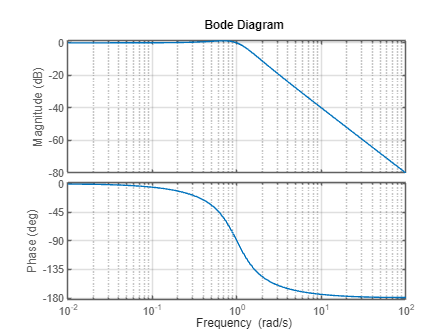


% Bode plot
figure;
bode(G);
%title('Bode Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/bode_G.png', '-dpng', '-r300');

syms k real

% closed-loop matrix
A_cl = A - B * k * C;

eigvals = eig(A_cl);
stability_range = solve(real(eigvals) < 0, k, 'Real', true);

% Display result
disp('Range of K for stability:')

Range of K for stability:


disp(stability_range)

$$0$$

k_vals = linspace(-10, 10, 1000);   % Negative k values

% Plot root locus
figure; hold on;
rlocus(G, k_vals);
xlabel('Real Axis')
ylabel('Imaginary Axis')
title('Root Locus')
grid on;
legend('Positive k', 'Negative k')

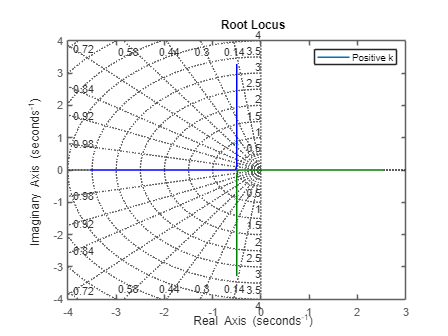

hold off;
print(gcf, 'figures/rlocus_G.png', '-dpng', '-r300');

G_dashed = Hinfty(G);

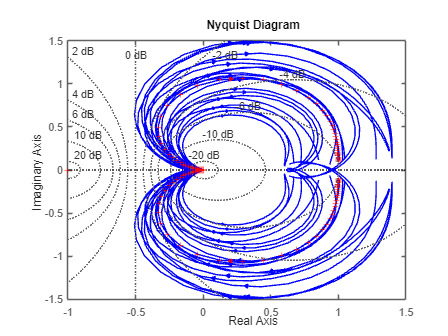

figure;
nyquist(G_dashed,'b',G_dashed.NominalValue,'r+',logspace(-1,3,120));
%title('Nyquist Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/nyquist_G.png', '-dpng', '-r300');

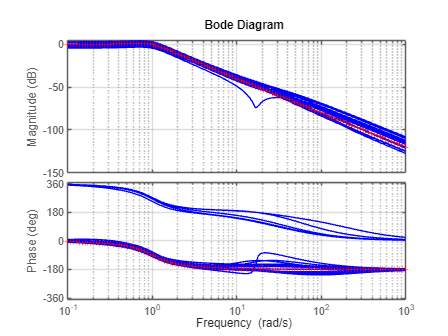


% Bode plot
figure;
bode(G_dashed,'b',G_dashed.NominalValue,'r+',logspace(-1,3,120))
%title('Bode Plot of G'); %caption will be in report
grid on;
print(gcf, 'figures/bode_G.png', '-dpng', '-r300');